Test Case


$$P(s) = \frac{s^4+10s^3-12s^2-104s+160}{s^6+170s^5+8400s^4+148000s^3+800000s^2}=\frac{b(s)}{a(s)}$$


syms s
b = [1 10 -12 -104 160];
a = [1 170 8400 148000 800000 0 0];
P = tf(b,a);


$$C_0 \left(s\right)=\frac{q\left(s\right)}{p\left(s\right)}$$


C0 = tf(pidtune(P, "PIDF"));
q = C0.num{1};
p = C0.den{1};
% c(s) = a(s)p(s) + b(s)q(s)
cpoly1 = conv(a, p);
cpoly2 = conv(b, q);

% 确保数组长度相同
max_len = max(length(cpoly1), length(cpoly2));
cpoly1_padded = [zeros(1, max_len - length(cpoly1)), cpoly1];
cpoly2_padded = [zeros(1, max_len - length(cpoly2)), cpoly2];

% 现在可以相加
cpoly = cpoly1_padded + cpoly2_padded;
r = roots(cpoly);


$$c\left(s\right)=f\left(s\right)h\left(s\right)$$


n = numel(a) - 1;       
m = numel(p) - 1;
[f, h] = split_roots_real_coeffs(r, n);
% 验证
assert(length(f)-1 == n, 'deg f != n');
assert(length(h)-1 == m, 'deg h != m');



$$c\left(s\right)=a\left(s\right)p\left(s\right)+b\left(s\right)q\left(s\right)=f\left(s\right)h\left(s\right),\deg \left(f\right)=\deg \left(a\right),\deg \left(h\right)=\deg \left(p\right)$$



$$M\left(s\right)=\frac{a\left(s\right)}{f\left(s\right)},N\left(s\right)=\frac{b\left(s\right)}{f\left(s\right)},X\left(s\right)=\frac{p\left(s\right)}{h\left(s\right)},Y\left(s\right)=\frac{q\left(s\right)}{h\left(s\right)}$$


% 验证：deg f = n, deg h = m
assert(length(f)-1 == n, 'deg f != n');
assert(length(h)-1 == m, 'deg h != m');
M = tf(a,f);
N = tf(b,f);
X = tf(p,h);
Y = tf(q,h);


$$Q_1 \left(s\right)=\frac{f\left(s\right)}{b_s \left(s\right)b_u \left(0\right)}\prod_{i=1}^k \frac{\alpha_i }{s+\alpha_i }$$



$$\frac{f\left(s\right)}{b_s \left(s\right)b_u \left(0\right)}$$


% 根据理论修复Q1计算
alphas = [3 3 3 3]; 

b_roots = roots(b);
stable_roots = b_roots(real(b_roots) < 0);  
unstable_roots = b_roots(real(b_roots) >= 0); 

% 构建b_s(s)和b_u(s)
b_s = poly(stable_roots);    
b_u = poly(unstable_roots);  
b_u_0 = polyval(b_u, 0);


计算k所需要的数值 


$$k\ge \deg \;f\left(s\right)-{\deg \;b}_s \left(s\right)$$


% ========== 新增：计算k值 ==========
deg_f = length(f) - 1;           % deg f(s)
deg_b_s = length(b_s) - 1;       % deg b_s(s)
min_k = deg_f - deg_b_s;
current_k = length(alphas);
if current_k < min_k
    warning('k值不足: 当前k=%d, 需要k≥%d。自动调整k值。', current_k, min_k);
    % 补充额外的α值
    additional_alphas = 5 * ones(1, min_k - current_k);  % 使用较小的α值
    alphas = [alphas, additional_alphas];
    fprintf('调整后的alphas: %s\n', mat2str(alphas));
end

b_u_0_value = polyval(b_u, 0);  % 这是标量值
denominator_poly = b_s * b_u_0_value;  % b_s(s) * b_u(0)
Q1_base = tf(f, denominator_poly);

% 然后乘以抵消项
for a_i = alphas
    Q1_base = Q1_base * tf(a_i, [1 a_i]);
end

Q1 = minreal(Q1_base);

Q2 = tf(1, [1 10]);



$$T\left(P\right)=\left\lbrack \frac{Q_1 \left(s\right)}{X\left(s\right)-N\left(s\right)Q_2 \left(s\right)},\frac{Y\left(s\right)+M\left(s\right)Q_2 \left(s\right)}{X\left(s\right)-N\left(s\right)Q_2 \left(s\right)}\right\rbrack$$


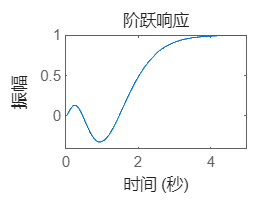

T = (P*C1)/(1+P*C2);
C1 = minreal(Q1/(X-N*Q2));
C2  = minreal((Y+M*Q2)/(X-N*Q2));
step(T);